# 4G-LTE downlink receiver

## Exercise 1

Using the similar token tracing method demonstrated in the lecture example, we first build a corresponding model on the 5XIE0 Workbench. As the following:

To find the latency we define several connecting paths between the input and output ports in the above code, such that for *symbol 0* it is `DCod0-SRC0`, for *symbol 1* it is  `DCod1-SRC1`, and so on. This can be shown in matrix form as below:

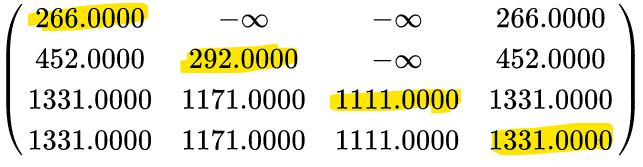

We have highlighted the diagonal entries, as they represent the latencies for (from to left to bottom right) *symbol 0, symbol 1, symbol 2*, and the entire *subframe*, respectively.

We are also aware that there could be multiple possible dominant paths, hence we take the initial tokens into consideration. Now the latencies become dependent of the period. For the maximum throughput (period = 0), we derive the matrix:

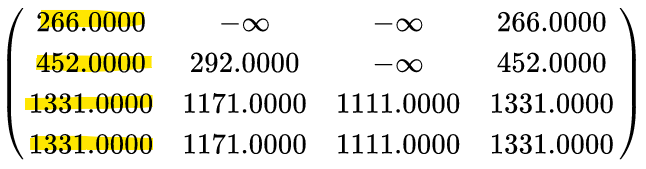

We are interested in the left most column since the initial token on the left side of the data flow graph has the longest path to the end of the decoding task. The highlighted entries from top to bottom are the latencies for the *symbol 0, symbol 1, symbol 2*, and the s*ubframe *at maximum throughput.

## Exercise 2

In the real-life deployment, there may be hardware constraints such that a task can only process one symbol at a time. Therefore we will modify the data flow graph to accommodate the temporal dependency between the symbols of the same task. We will show the steps in iterations, so the reader could follow more easily.

- **DMod task:**

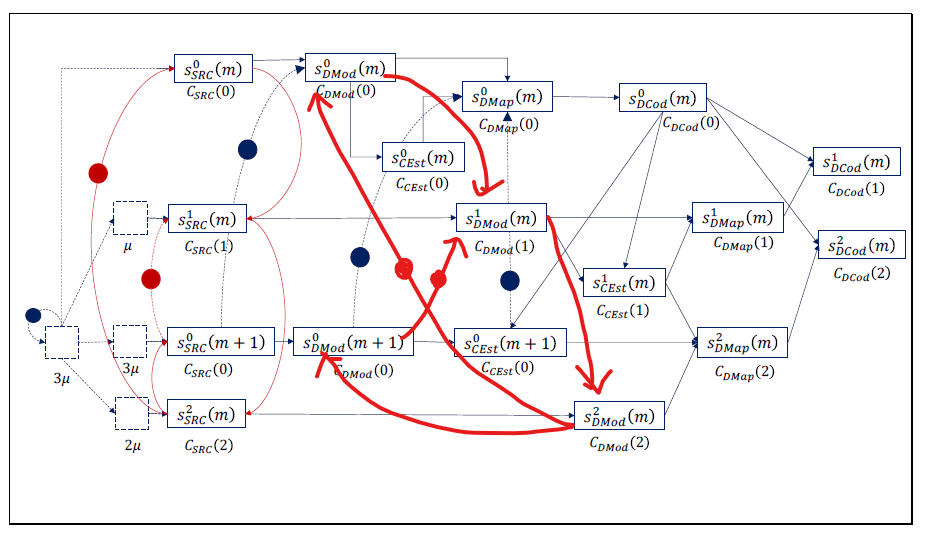

- **DMap Task**

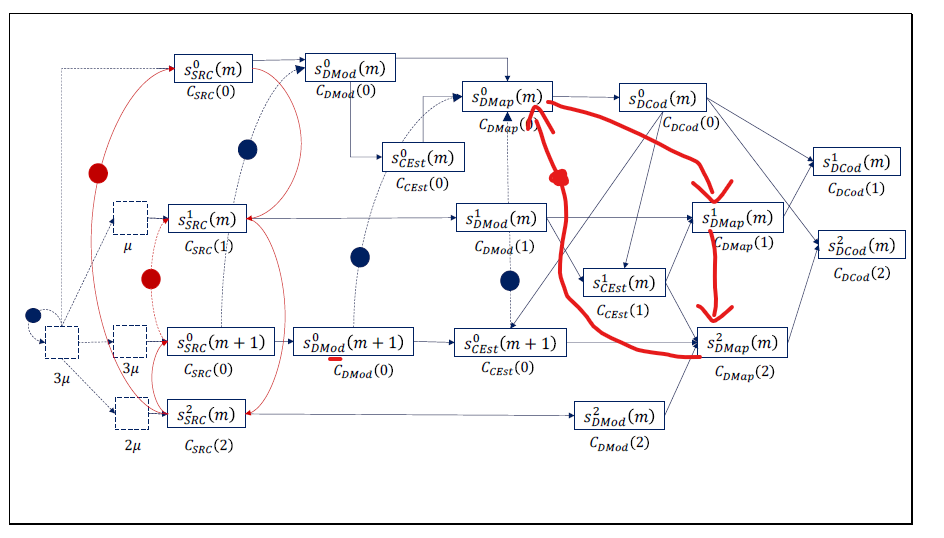

- **DCod Task**

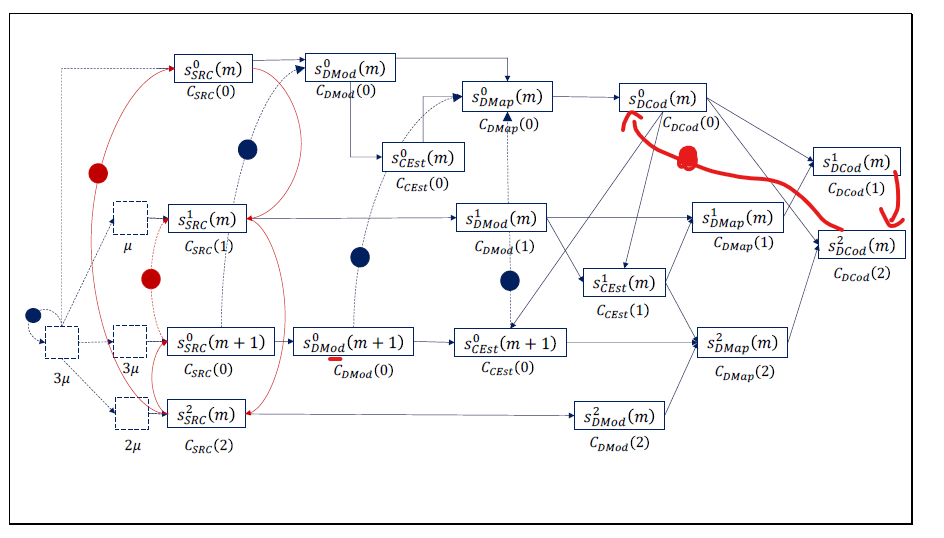

- **CEst Task**

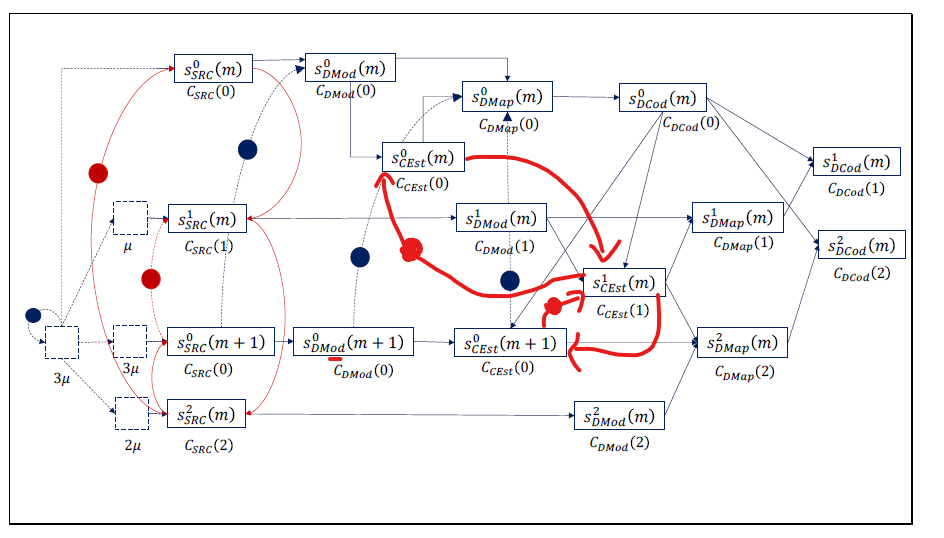

Note that apart from the initial token added to start the processor, we also add a few extra tokens from the `(m+1)` subframe for the synchronization and avoiding deadlock.

We build the overall deployment on the Workbench tool. There are now 12 tokens in total. The result is shown as (might need to zoom-in):

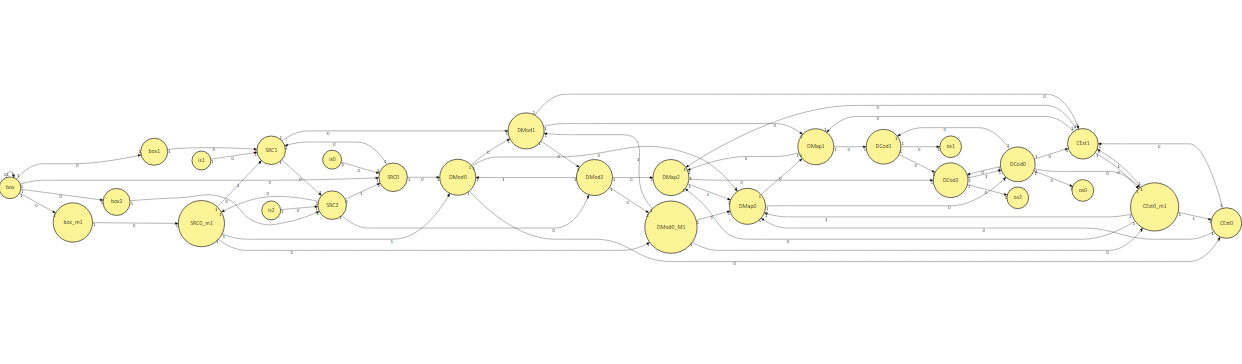

## Exercise 3

Once we accquire the deployment graph as in Exercise 2, we can derive the matrix ***A***, which describes the length relationships of the tokens to their next iteration. Furthermore we can convert ***A*** to a precedence graph, in which its a digraph with the nodes being tokens and the weighted edges being the path lengths. Hence the the cycle mean equals to the sum of the weights on all edges of the cycle divided by the number of edges in the cycle.

According to the eigenvalue equation of the max-plus algebra:


$$Ax=�\lambda \otimes x$$


We observe that the largest eigenvalue is in fact corresponding the MCM of the precedence graph of ***A***, see (Baccelli et al. 1992) for the detailed mathematics derivation.

Filling in the firing times, we get the matrix ***A*** as:

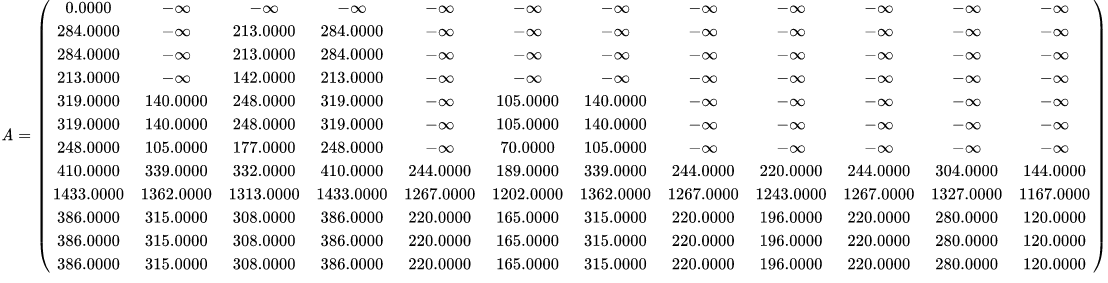

Solving the largest eigenvalue, we get `MCM=1243`, and for an individual symbol, it is equal to `MCM/3=414.33`

## Exercise 4

Similar to that of Exercise 1, we compute the ***D*** matrix (`row: input port, col: output port`) and take the diagonal entries as latencies for (from to left to bottom right) *symbol 0, symbol 1, symbol 2*, and the s*ubframe:*

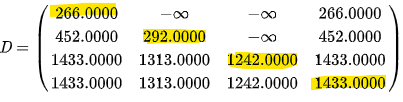

For the latencies when the throughput is maximum, we compute the C matrix and find the longest path to the end of decoding. It is corresponding to teh entries at the left most column. Below shows the latencies in the order from top to bottom for the *symbol 0, symbol 1, symbol 2*, and the s*ubframe *at period = 0.

## **Exercise 5**

Since we are more interested in how the latency varies over period, therefore we resort to making a automated python script to traverse across the data flow graph and generate a matrix with variables in the entries (similar implementation is possible with MATLAB, e.g., `digraph(A)`, `maxflow(G,s,t)`). below is the resultant matrix ***A*** we get: 

## **Exercise 6**

Now we will verify the MCM and latency using the max-plus toolbox.

clear all; clc;
mu=0;
A=[
    0+3*mu -inf -inf -inf -inf -inf -inf -inf -inf -inf -inf -inf ;
    71+6*mu -inf -inf -inf 284 213 -inf -inf -inf -inf -inf -inf ;
    106+6*mu 140 -inf -inf 319 248 140 105 -inf -inf -inf -inf ;
    166+6*mu 315 220 220 386 308 315 165 280 120 220 196 ;
    71+5*mu -inf -inf -inf 213 142 -inf -inf -inf -inf -inf -inf ;
    71+6*mu -inf -inf -inf 284 213 -inf -inf -inf -inf -inf -inf ;
    106+5*mu 105 -inf -inf 248 177 105 70 -inf -inf -inf -inf ;
    106+6*mu 140 -inf -inf 319 248 140 105 -inf -inf -inf -inf ;
    166+4*mu 255 160 160 326 166 255 95 220 60 160 136 ;
    166+6*mu 315 220 220 386 308 315 165 280 120 220 196 ;
    190+6*mu 339 244 244 410 332 339 189 304 144 244 220 ;
    1171+6*mu 1362 1267 1267 1433 1313 1362 1202 1327 1167 1267 1243 ;
]; 

The MCM is equal to:

% MCM subframe
mp_mcm(A)

ans = 1243

And the MCM per symbol is equal to:

% MCM symbol
mp_mcm(A)/3

ans = 414.3333

We can also plot the latency against the period (select an option in the drop-down list below):

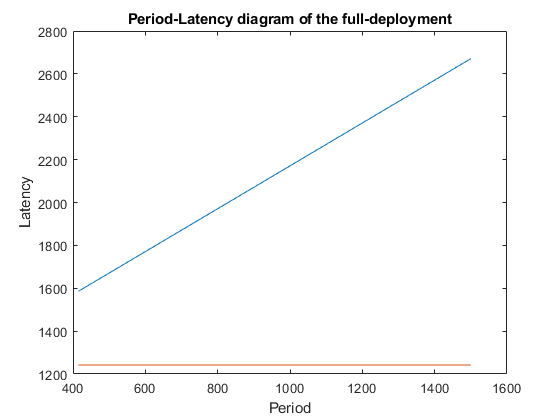

figure;
Early_schedule_latency = [];
Late_schedule_latency = [];
range = [415:1:1500];
for mu = range 
    A=[
        0+3*mu -inf -inf -inf -inf -inf -inf -inf -inf -inf -inf -inf ;
        71+6*mu -inf -inf -inf 284 213 -inf -inf -inf -inf -inf -inf ;
        106+6*mu 140 -inf -inf 319 248 140 105 -inf -inf -inf -inf ;
        166+6*mu 315 220 220 386 308 315 165 280 120 220 196 ;
        71+5*mu -inf -inf -inf 213 142 -inf -inf -inf -inf -inf -inf ;
        71+6*mu -inf -inf -inf 284 213 -inf -inf -inf -inf -inf -inf ;
        106+5*mu 105 -inf -inf 248 177 105 70 -inf -inf -inf -inf ;
        106+6*mu 140 -inf -inf 319 248 140 105 -inf -inf -inf -inf ;
        166+4*mu 255 160 160 326 166 255 95 220 60 160 136 ;
        166+6*mu 315 220 220 386 308 315 165 280 120 220 196 ;
        190+6*mu 339 244 244 410 332 339 189 304 144 244 220 ;
        1171+6*mu 1362 1267 1267 1433 1313 1362 1202 1327 1167 1267 1243 ;
    ];
    
    % Symbol 0
    C0=[
        0+3*mu -inf -inf -inf 0 -inf -inf -inf -inf -inf -inf -inf ;
        266+3*mu 195 100 100 266 -inf 195 -inf 160 -inf 100 76 ;
    ];
    
    % Symbol 1
    C1=[
        0+4*mu -inf -inf -inf 71 0 -inf -inf -inf -inf -inf -inf ;
        292+4*mu 381 286 286 452 292 381 221 346 186 286 262 ;
    ];
    
    % Symbol 2
    C2=[
        0+5*mu -inf -inf -inf 142 71 -inf -inf -inf -inf -inf -inf ;
        1171+6*mu 1362 1267 1267 1433 1313 1362 1202 1327 1167 1267 1243 ;
    ];
    
    % Subframe
    Cf=[
        0+3*mu -inf -inf -inf 0 -inf -inf -inf -inf -inf -inf -inf ;
        1171+6*mu 1362 1267 1267 1433 1313 1362 1202 1327 1167 1267 1243 ;
    ];
    
   % Choose one to verify
   C=C2;
   
   % Check whether the MCM does not exceed the period 3*mu of the source
   if mp_mcm(A) > 3*mu
       error("Period of the source is smaller than MCM, please choose mu larger than: " + mp_mcm(A)/3);
   end
   
   % Determine earliest possible periodic schedule
   x = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
   while max(x ~= max(x,mp_multi(A,x) - 3*mu))
      x = max(x,mp_multi(A,x) - 3*mu);
   end    

   Early_schedule_symbol = mp_multi(C,x);
   Early_schedule_latency = [Early_schedule_latency Early_schedule_symbol(2)-Early_schedule_symbol(1)];
  
   % Determine latency optimal schedule for the first symbol as output      
   x = mpm_multi(-C',[inf; 0]);
   while max(x ~= min(x,mpm_multi(-A',x) + 3*mu))
      x = min(x,mpm_multi(-A',x) + 3*mu);
   end 
   
   Late_schedule = x;
   Late_schedule_symbol = mp_multi(C,Late_schedule);
   Late_schedule_latency = [Late_schedule_latency Late_schedule_symbol(2)-Late_schedule_symbol(1)];
end

plot(range,[Early_schedule_latency;Late_schedule_latency])
title("Period-Latency diagram of the full-deployment")
xlabel("Period")
ylabel("Latency")

## **Exercise 7**

Below is the Gantt chart of our model, runs for five iterations, using period = MCM. Note that due to the extra dependencies we introduce in Exercise 2, at any given moment there is only one symbol of the same task type occupying the corresponding hardware. The strips in the chart will not overlap if they belong to the same task, i.e., `SRC0` and `SRC1`...etc are mutually exclusive.

Another observation is that symbol 0 finish its task the earliest and does not depends on other symbol, so varying the period does not trade off its latency. This is reflected both in the Gannt chart and the Period-Latency plot in the Exercise 6. Meanwhile, increasing the period will decrease the latency of s`ymbol 1`. In contrast the latency of s`ymbol 2` will increase (hence followed teh whole subframe) as the period increases, this is due to the data symbol consuming the most time to decode, therefore it is the bottleneck of the system. Meaning that it is more of the other symbols which have to wait for s`ymbol 2`, and not the opposite.   

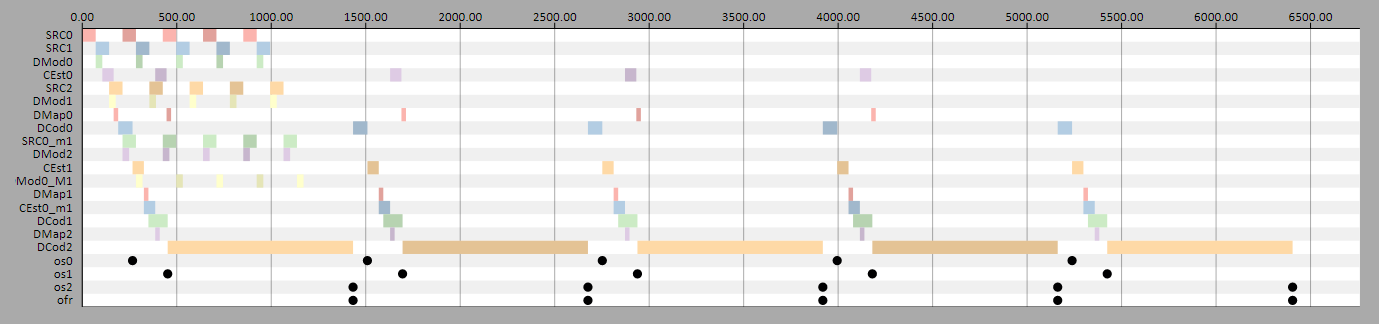

## **Reflection**

There are a slight difference in some matrix entries between the Workbench and the Python path-walking tool. We attribute this issue to the reason of the superfluous actors in the data flow graph, e.g., SRC0(m), DMod0(m)...etc. As these actors are significant only in the first iteration, but causing a potential conflict during path tracing of the algorithm. Although the final MCM value is not affected (and should not be), it is suggested to remove those actors to simplify the system.

With regard to the max-plus algebra, many theorem are taken for granted from the 5XIE0 handouts. The lacking of rigor suggests a more careful study of the relevant mathematics may benefit us more in the future work. 

Finally we are very thankful to the fellow student, Nikola Felkaroski, for their tremendous efforts in developing the said Python "path traversal automation tool". It has been shown to be very helpful in this assignment. 

## **Bibliography**

Some useful frameworks/tools when working with a directed graph:

- [https://nl.mathworks.com/help/matlab/ref/graph.maxflow.html](https://nl.mathworks.com/help/matlab/ref/graph.maxflow.html)

- [https://networkx.org/documentation/stable//index.html](https://networkx.org/documentation/stable//index.html)

- [http://cm.ics.ele.tue.nl/5xie0/documentation/05_maxplus](http://cm.ics.ele.tue.nl/5xie0/documentation/05_maxplus)

In case one is really into this kind of mathemetics:

- Baccelli, Francois et al. (1992). Synchronisation and Linearity. An Algebra for Discrete Event Systems. Wiley